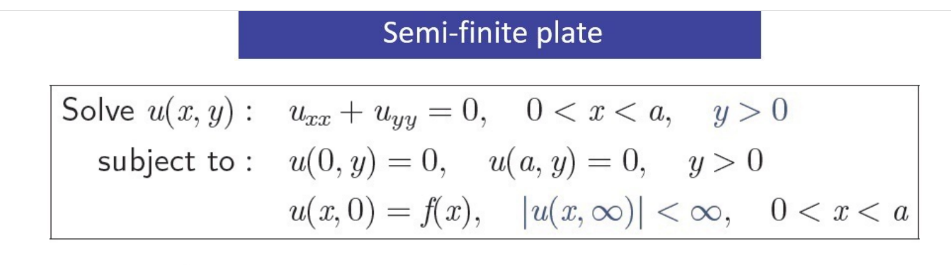

**Separation part**

clear
clc
syms x y u(x,y) f(x) a
assume(a,"positive")
LaplaceEq = diff(u,x,2) == -diff(u,y,2)

$$LaplaceEq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=-\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

x0 = u(0,y) == 0;
xa = u(a,y) == 0;
y0 = u(x,0) == f(x);
syms X(x) Y(y)
SepVar = subs(LaplaceEq,u(x,y),X(x)*Y(y));
x0 = subs(x0,u(0,y),X(0))

$$x0 = X\left(0\right)=0$$

xa = subs(xa,u(a,y),X(a))

$$xa = X\left(a\right)=0$$

y0 = subs(y0,u(x,0),Y(0))

$$y0 = Y\left(0\right)=f\left(x\right)$$

y_inf = Y(inf) == str2sym('bounded')

$$y\_inf = Y\left(\infty \right)=\mathrm{bounded}$$

SepVar = SepVar/(X(x)*Y(y))

$$SepVar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

syms lambda 
assume(lambda,"positive")
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqY = var(2) == -lambda^2

$$eqY = -\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=-\lambda^{2}$$

X(x) = subs(dsolve(eqX,x0),str2sym('-C1'),'C2')

$$X(x) = C_{2}\,\sin\left(\lambda \,x\right)$$

Y(y) = subs(dsolve(eqY),'C1',0)

$$Y(y) = C_{2}\,{\mathrm{e}}^{-\lambda \,y}$$

sln = subs(X,x,a) == 0;
[lambda,parameters,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{a}$$

syms A_n ustruct(x,y,n)
X(x,n) = subs(X,{'C2','lambda'},{1,lambda});
Y(y,n) = subs(Y,{'C2','lambda'},{A_n,lambda});
ustruct(x,y,n) = X(x,n)*Y(y,n)

$$ustruct(x, y, n) = A_{n}\,{\mathrm{e}}^{-\frac{\pi \,n\,y}{a}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)$$

**Fouriers integral**

f(x) = (x+0.5)^3;
ustruct = subs(ustruct,a,1)

$$ustruct(x, y, n) = A_{n}\,\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\pi \,n\,y}$$

a = 1;
An = 2/a*int(f*sin(pi*n*x/a),x,[0 a])

$$An = -\frac{2\,\left(6\,\sin\left(\pi \,n\right)+n^{3}\,\pi^{3}\,\left(\frac{27\,\cos\left(\pi \,n\right)}{8}-\frac{1}{8}\right)-\pi \,n\,\left(9\,\cos\left(\pi \,n\right)-3\right)-\frac{27\,n^{2}\,\pi^{2}\,\sin\left(\pi \,n\right)}{4}\right)}{n^{4}\,\pi^{4}}$$

syms sigma
LaplaceSol = [sigma ustruct]

$$LaplaceSol(x, y, n) = \left(\begin{array}{cc} \sigma & A_{n}\,\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\pi \,n\,y} \end{array}\right)$$

LaplaceSol = symsum(subs(ustruct,{A_n,a},{An,1}),n,1,inf)

Sol = symsum(subs(ustruct,A_n,An),n,1,30)

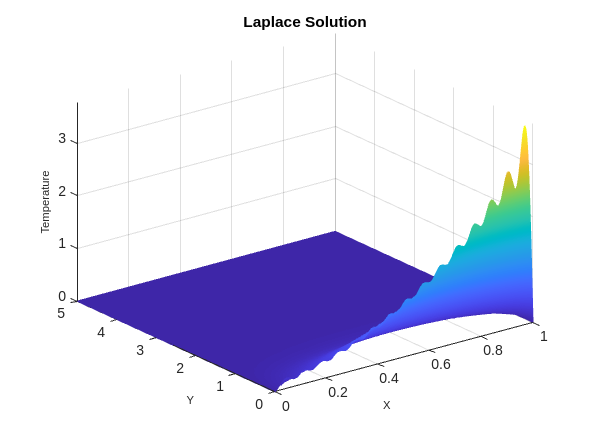

clf;figure
fsurf(Sol,[0 1 0 5],"EdgeColor","interp")
title("Laplace Solution")
xlabel('X','FontSize',8)
ylabel('Y','FontSize',8)
zlabel('Temperature','FontSize',8)

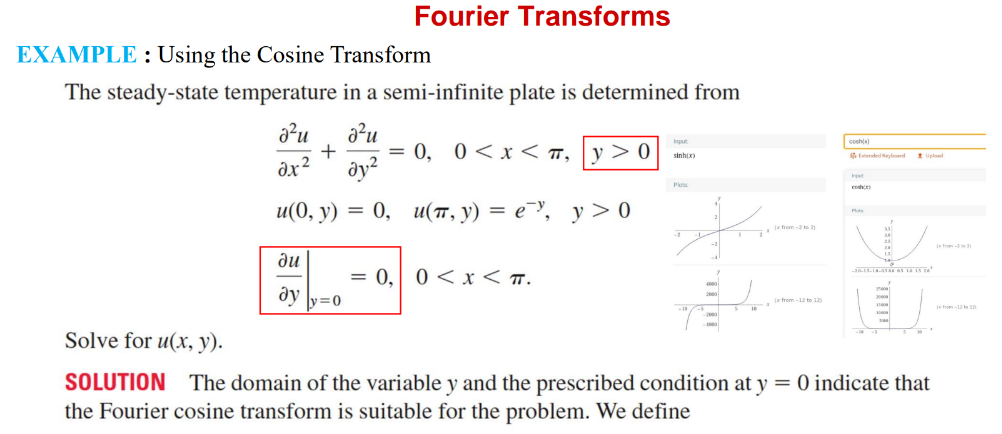

clear
clc
clearvars
syms x y w u(x,y) U_c(x,w) X(x) A B
Dy = diff(u,y);
D2y = diff(Dy,y);
D2x = diff(u,x,2);
eqn = fourier(D2x+D2y == 0,y,w);
eqn = expand(subs(eqn,{fourier(D2x,y,w),fourier(u,y,w)},{subs(D2x,{u,y},{U_c,w}),U_c+Dy(x,0)/w^2}))

$$eqn(x) = \frac{\partial^{2}}{\partial x^{2}}U_{c}\left(x,w\right)-\left({\left(\frac{\partial }{\partial y}u\left(x,y\right)\right)|}_{y=0}\right)-w^{2}\,U_{c}\left(x,w\right)=0$$

eqn = subs(eqn,[U_c(x,w),Dy(x,0)],[X(x),0])

$$eqn(x) = \frac{\partial^{2}}{\partial x^{2}}X\left(x\right)-w^{2}\,X\left(x\right)=0$$

sol = dsolve(eqn)

$$sol = C_{1}\,{\mathrm{e}}^{w\,x}+C_{2}\,{\mathrm{e}}^{-w\,x}$$

sol = collect(rewrite(sol,"sinhcosh"),["cosh","sinh"])

$$sol = \left(C_{1}+C_{2}\right)\,\cosh\left(w\,x\right)+\left(C_{1}-C_{2}\right)\,\sinh\left(w\,x\right)$$

sol = subs(sol,str2sym({'C1+C2','C1-C2'}),{A,B})

$$sol = A\,\cosh\left(w\,x\right)+B\,\sinh\left(w\,x\right)$$

A = solve(subs(sol,x,0) == 0,A)

$$A = 0$$

sol = subs(sol,sym('A'),A)

$$sol = B\,\sinh\left(w\,x\right)$$

B = subs(solve(sol == 1/(1+w^2),sym('B')),x,pi)

$$B = \frac{1}{\sinh\left(\pi \,w\right)\,\left(w^{2}+1\right)}$$

U_c(x,w) = subs(sol,sym('B'),B)

$$U\_c(x, w) = \frac{\sinh\left(w\,x\right)}{\sinh\left(\pi \,w\right)\,\left(w^{2}+1\right)}$$

u(x,y) = str2sym('2/pi')*int(U_c*cos(w*y),w,[0 inf])

$$u(x, y) = \frac{2\,\int_{0}^{\infty }\frac{\cos\left(w\,y\right)\,\sinh\left(w\,x\right)}{\sinh\left(\pi \,w\right)\,\left(w^{2}+1\right)}\mathrm{d}w}{\pi }$$